## Polar Overturning Conceptual Model

#### Live script to run experiments for LGM and HS1 and produce figures for collaboration with Patrick Blaser. Includes stable isotope calculation and internal conversion fluxes.

#### twnh Sep '21, Nov '22, May '23, Oct '23

Based on `run_POC_model.mlx` from H21.

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
clc
if(isempty(gcp))
    parpool('local',96) 
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


Exp G1: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM).

modelG1 = build_POC_model('NH_FSBSO_LGM_can') ;

------------------------------------------------------------------------------------------------------------------------
------------------------------------------------------------------------------------------------------------------------
 Solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   4.4272   4.5250   4.5560
 Polar    Water:                     -1.9481          |           35.7064          |  

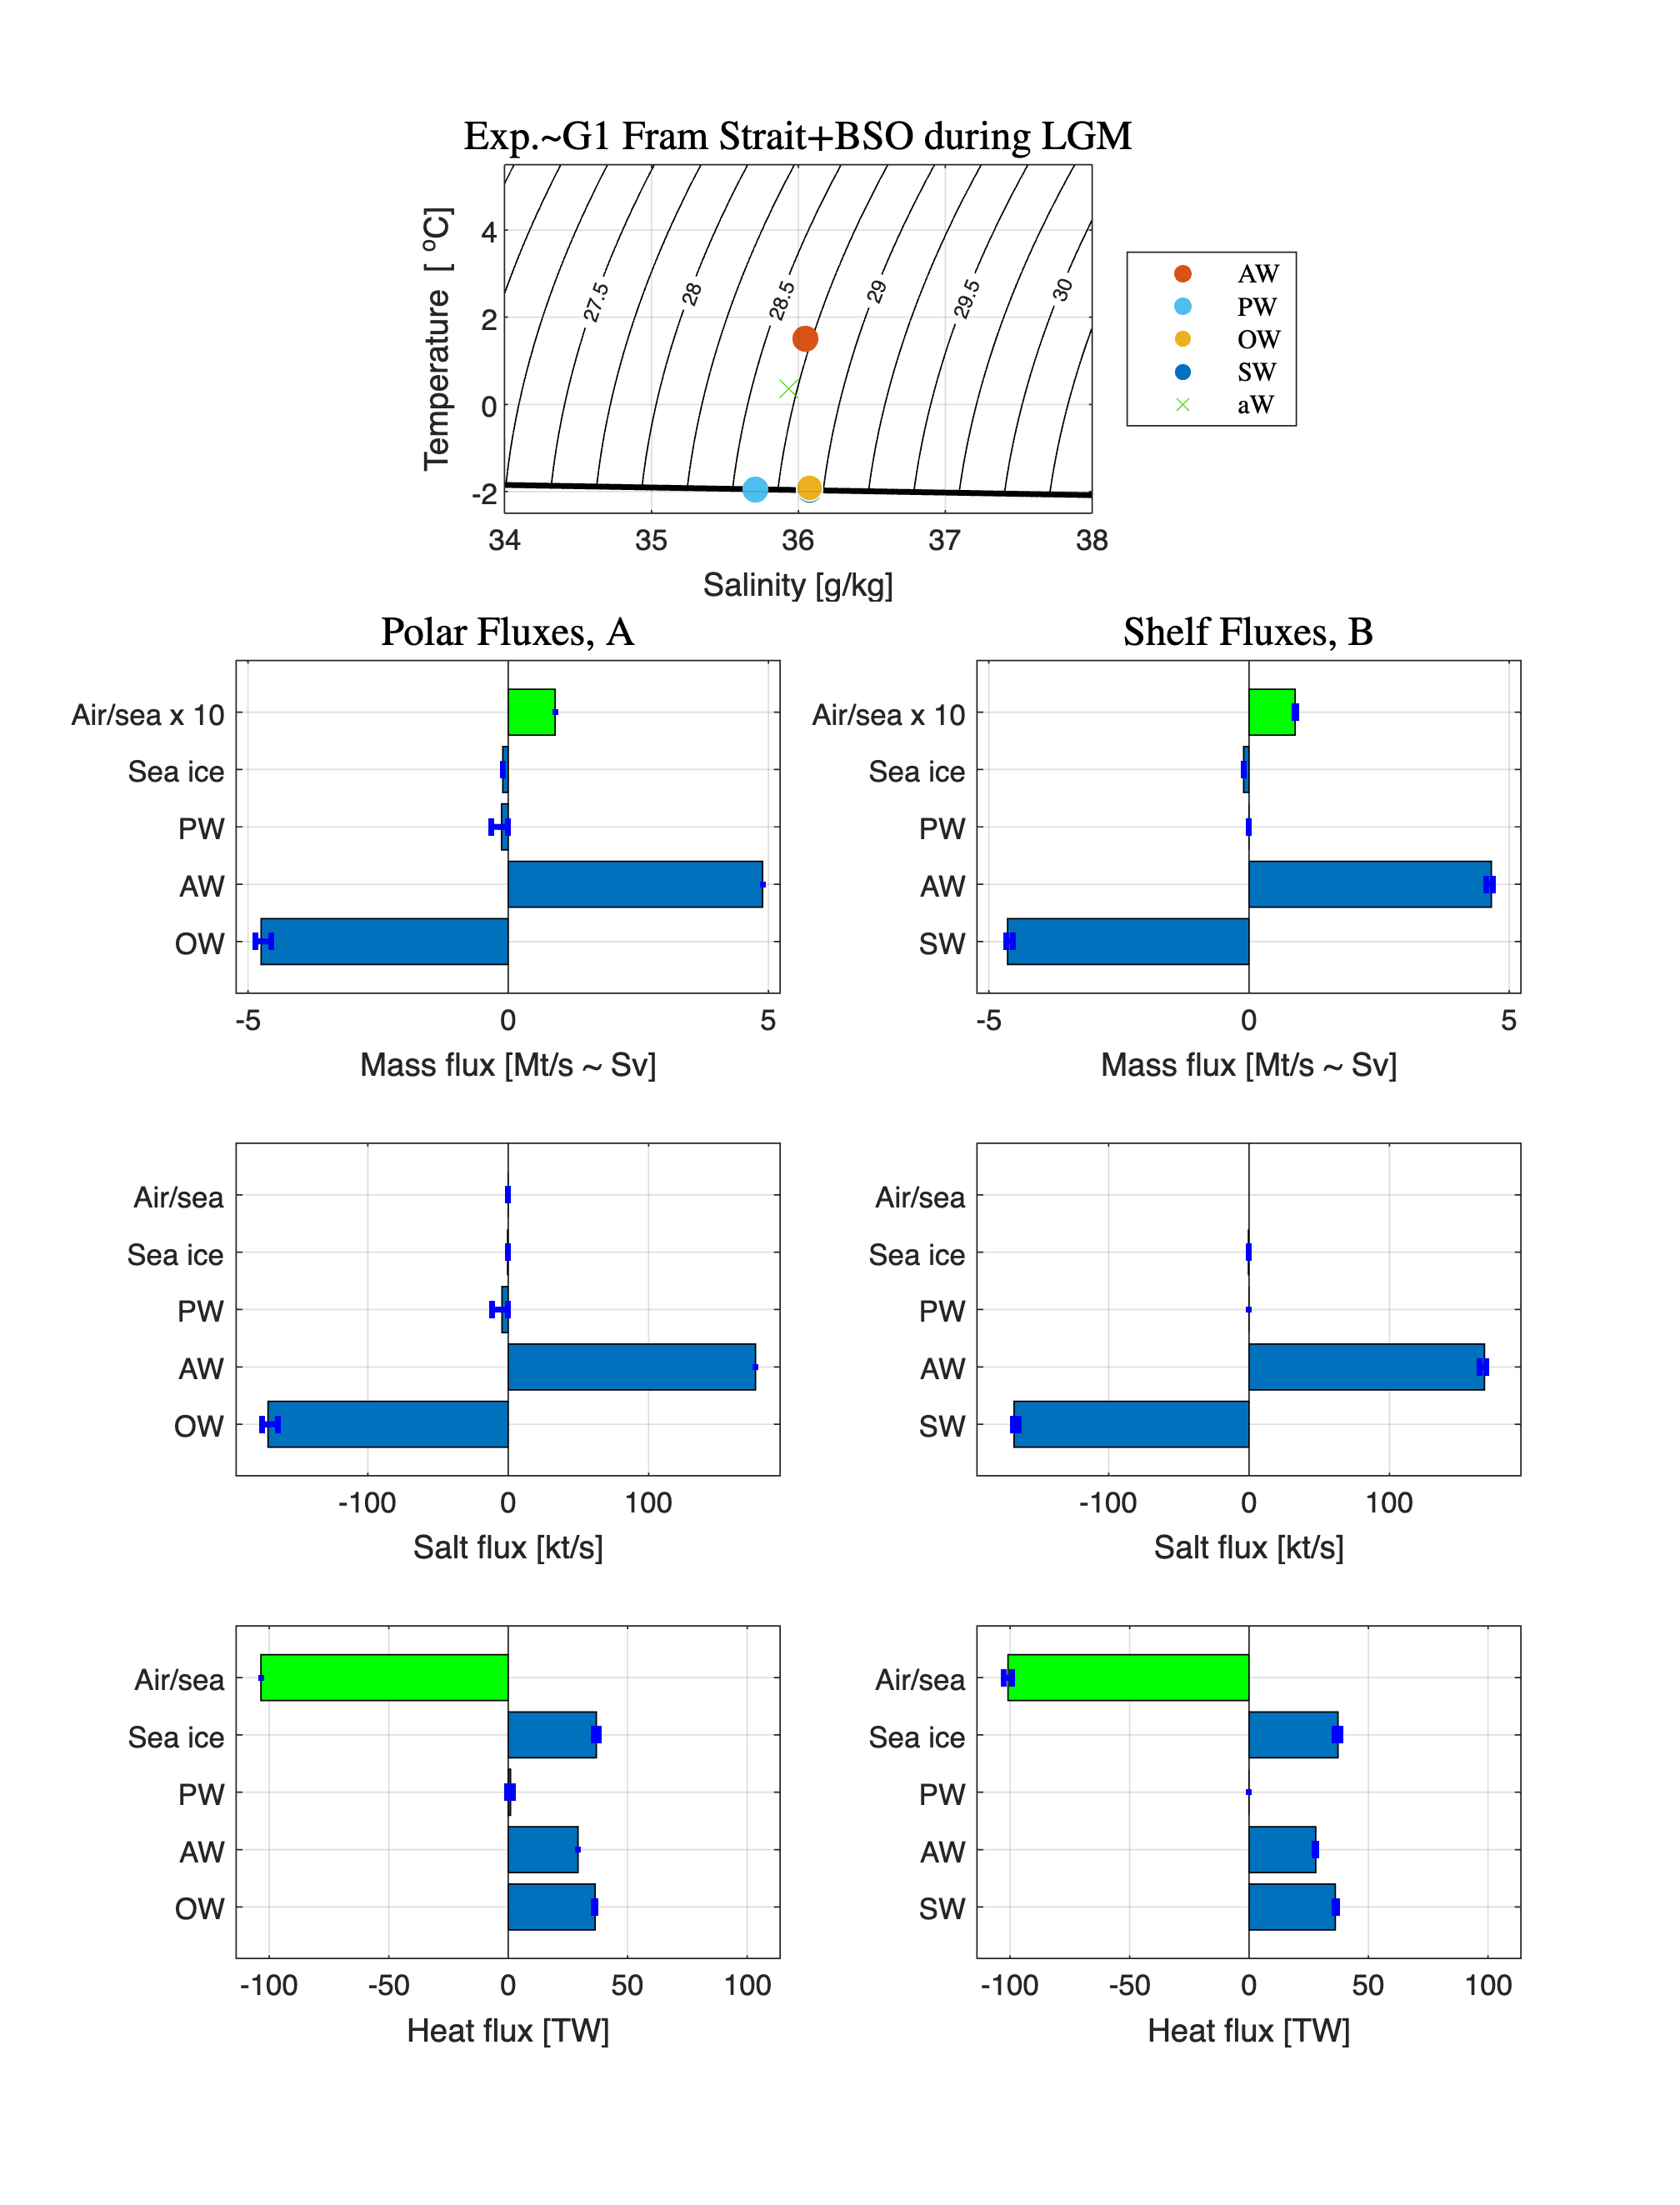

plot_POC_solution(modelG1)

modelG1 = build_stable_isotope_model(modelG1) ;

 Stable isotope solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           2000.15 to  2000.15  |     -0.15 to    -0.15          
 Overflow Water:           1999.34 to  1999.34  |     -0.55 to    -0.55          
 Sea ice:                  1999.32 to  1999.32  |     -0.56 to    -0.56           
 Shelf    Water:           1999.32 to  1999.32  |     -0.56 to    -0.56           



Exp G1b: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with warm AW.

modelG1b = build_POC_model('NH_FSBSO_LGM_hiT1') ;

------------------------------------------------------------------------------------------------------------------------
------------------------------------------------------------------------------------------------------------------------
 Solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      4.0000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             4.0000          |           36.0500          |   0.8089   1.3741   2.2538
 Polar    Water:                     -1.9189          |           35.20

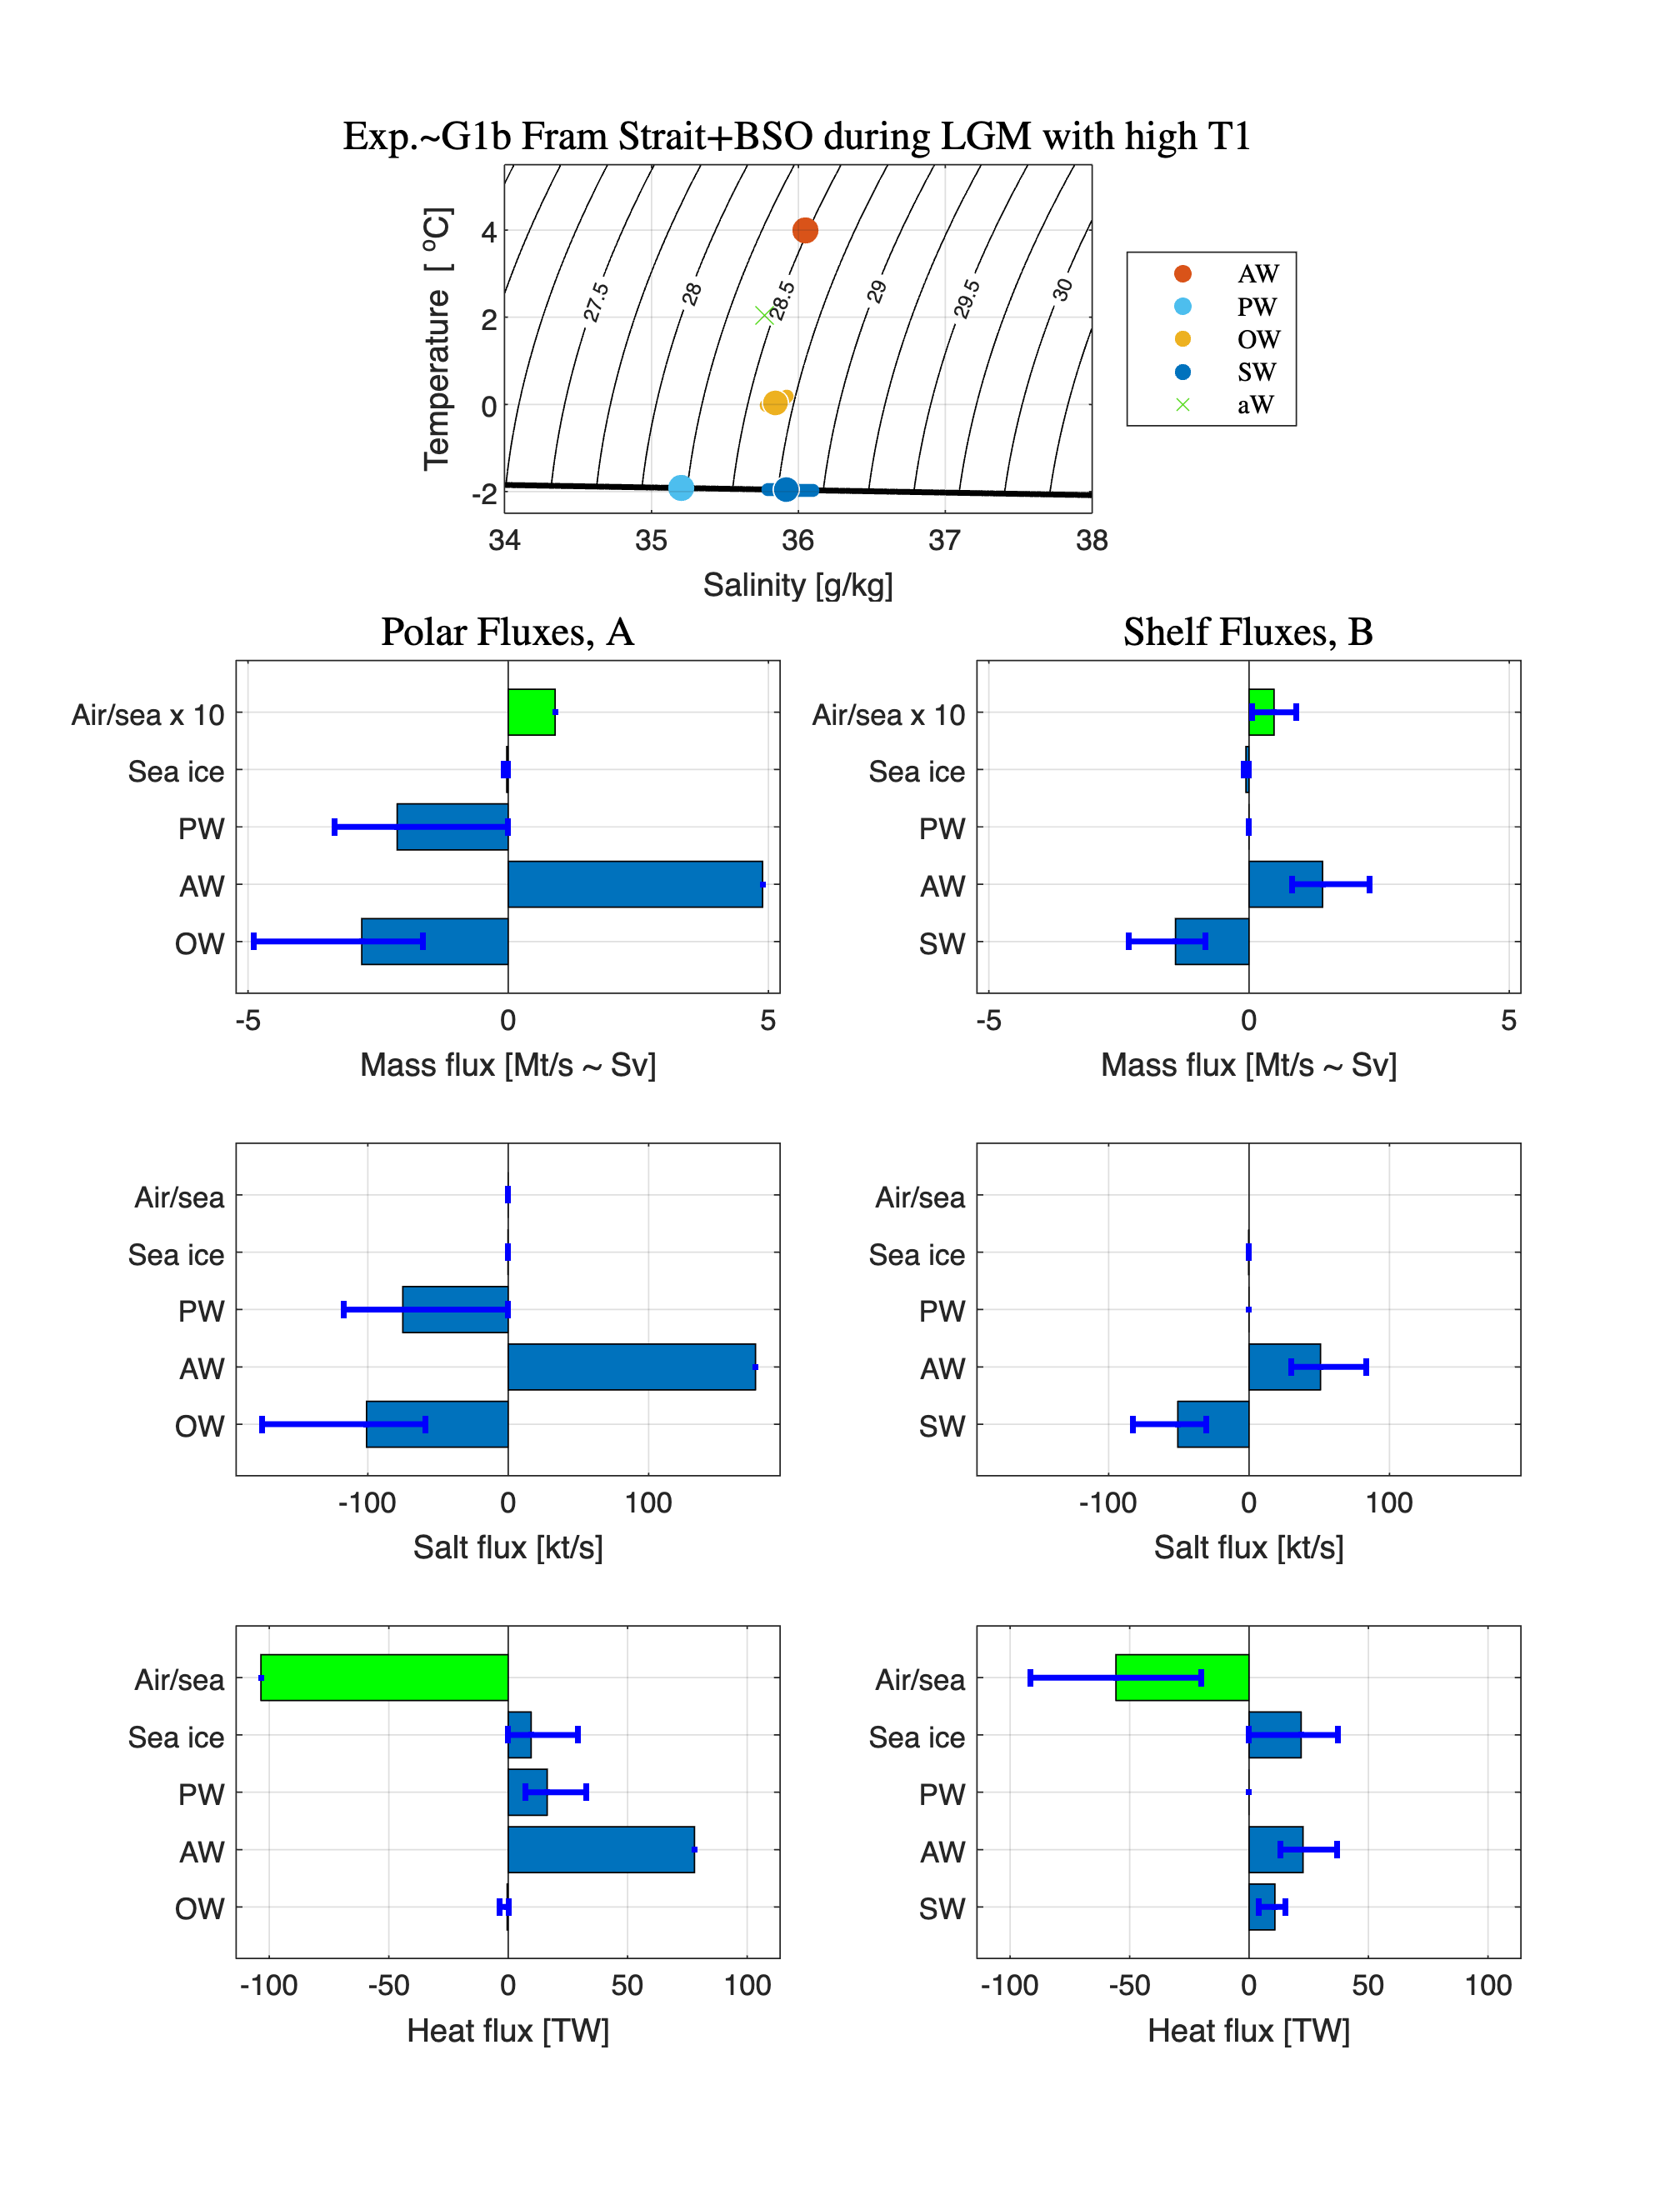

plot_POC_solution(modelG1b)

modelG1b = build_stable_isotope_model(modelG1b) ;

 Stable isotope solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           1999.71 to  1999.71  |     -0.37 to    -0.37          
 Overflow Water:           1999.11 to  1999.11  |     -0.67 to    -0.67          
 Sea ice:                  1998.02 to  1998.02  |     -1.21 to    -1.21           
 Shelf    Water:           1998.02 to  1998.02  |     -1.21 to    -1.21           



Exp G2: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with lower Q

modelG2 = build_POC_model('NH_FSBSO_LGM_lowQ') ;

------------------------------------------------------------------------------------------------------------------------
------------------------------------------------------------------------------------------------------------------------
 Solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   2.1685   2.6530   3.1441
 Polar    Water:                     -1.9481          |           35.7064 

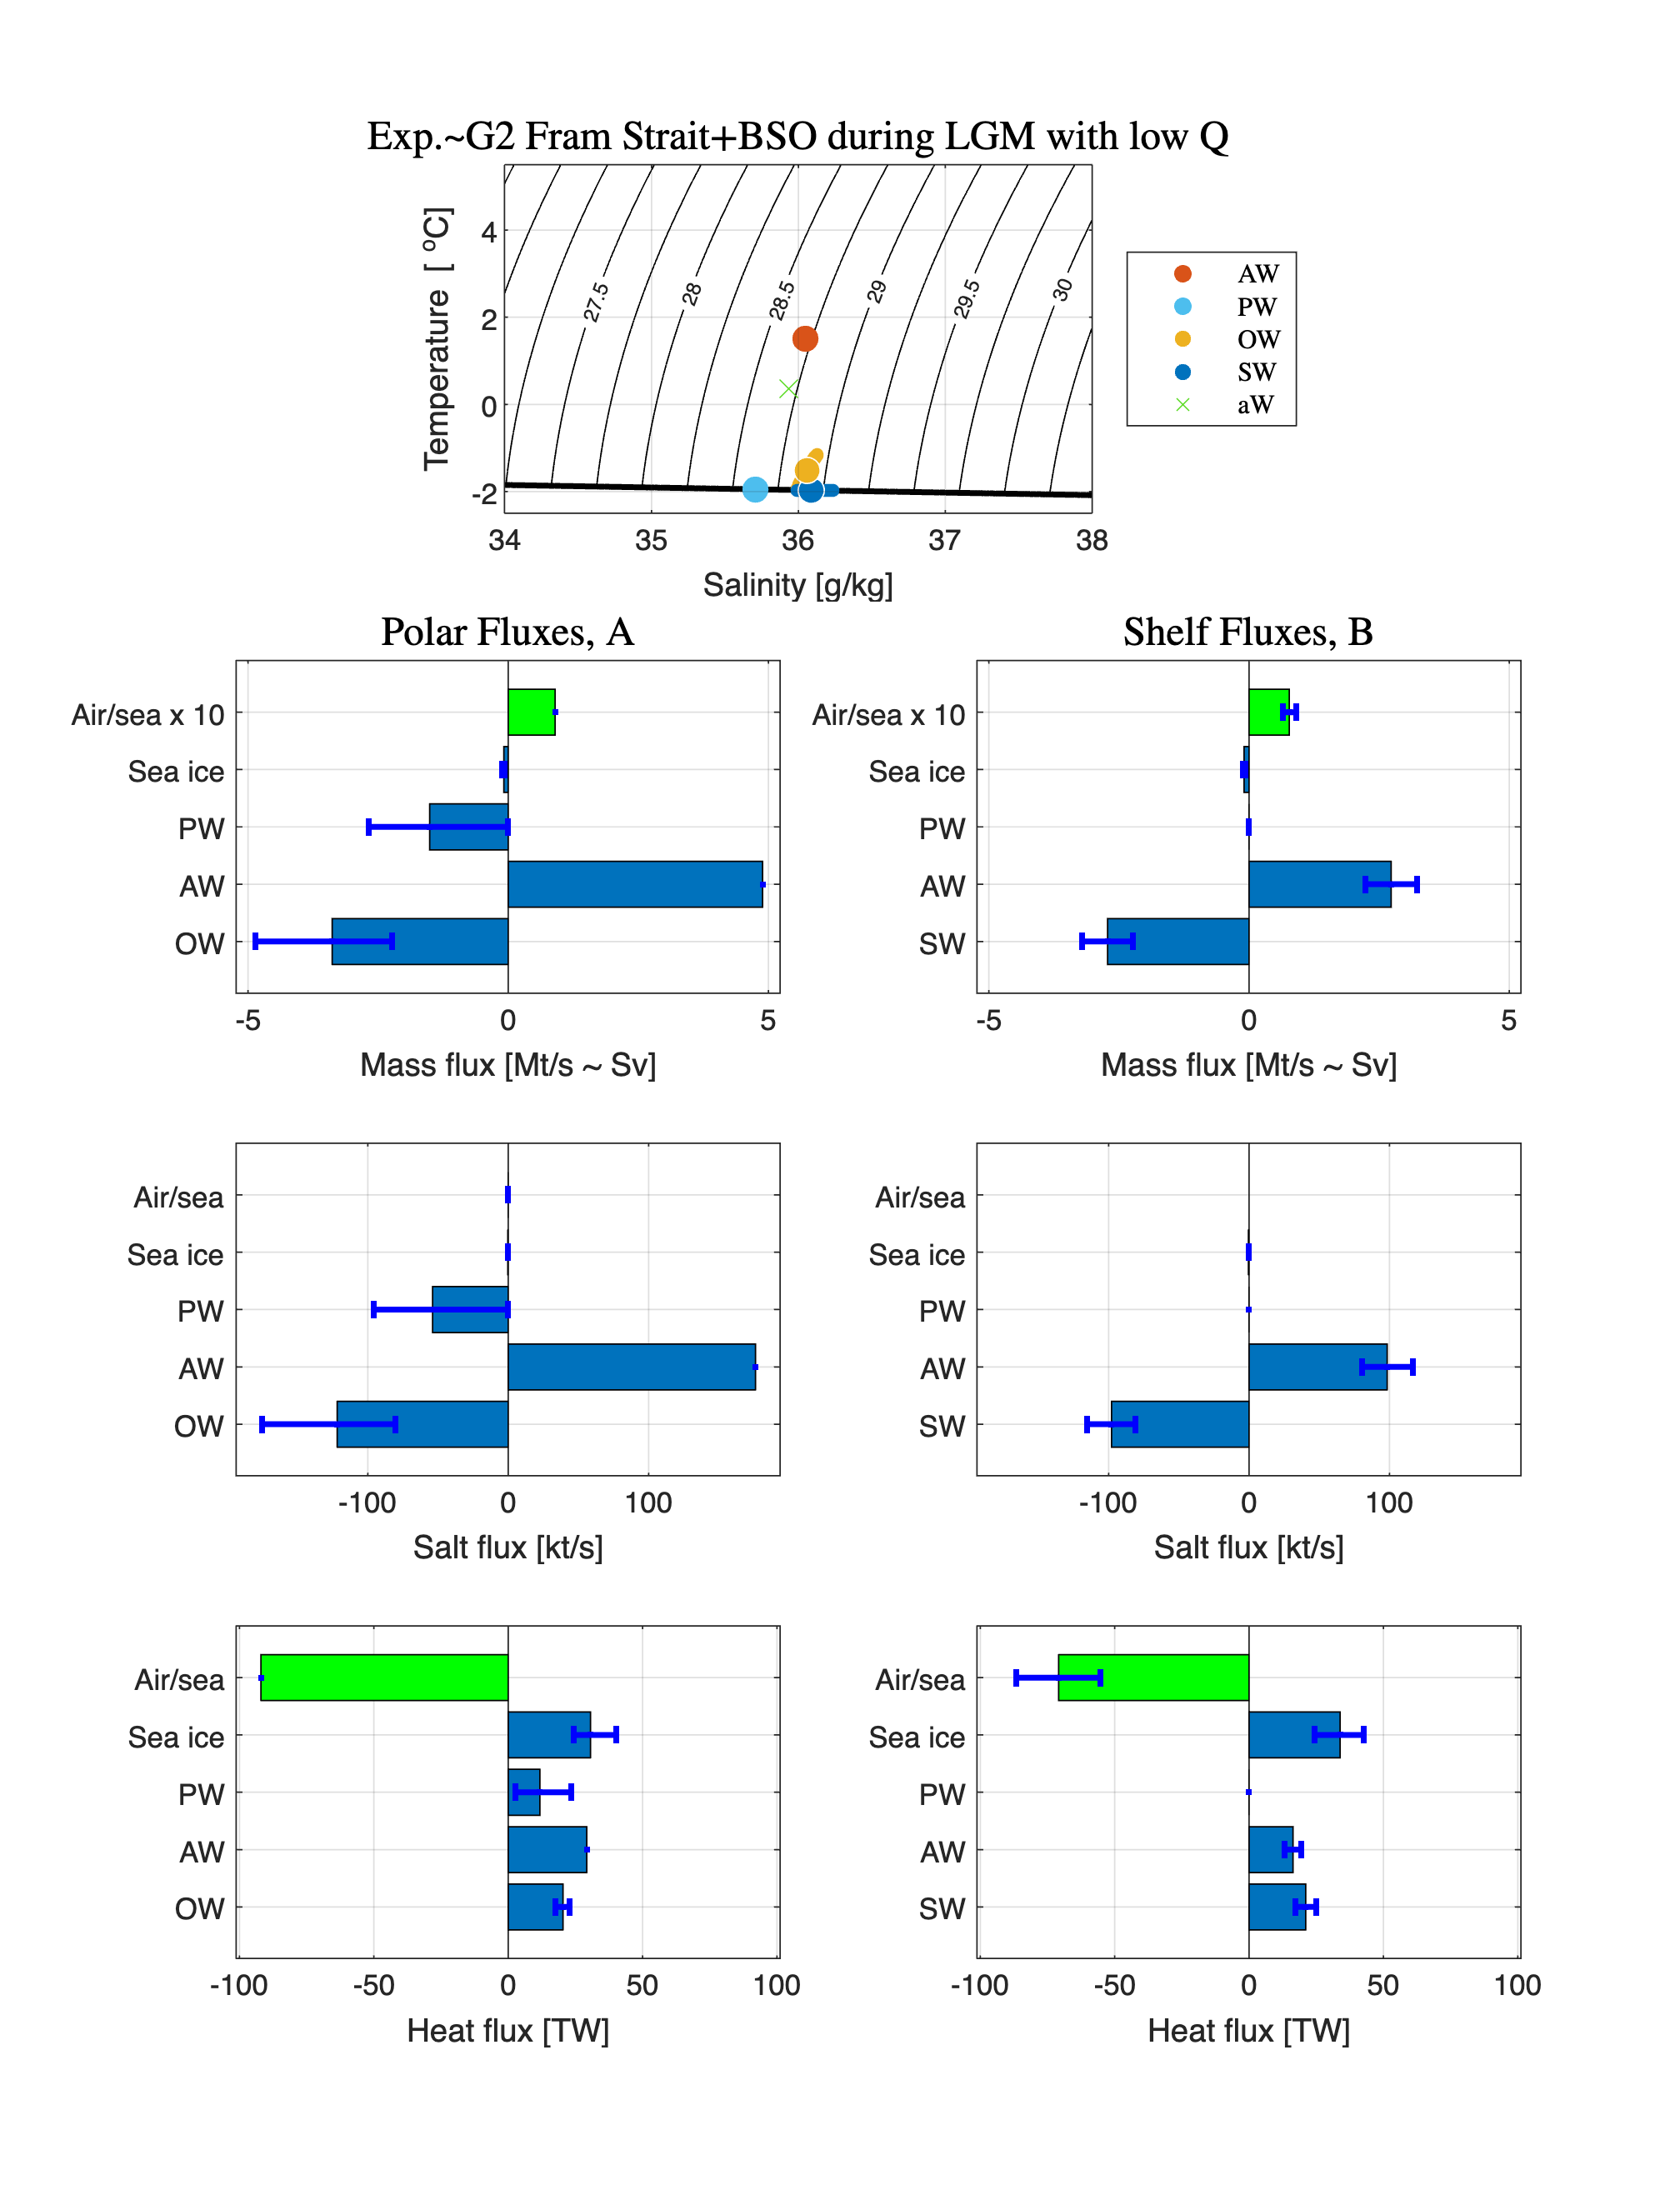

plot_POC_solution(modelG2)

modelG2 = build_stable_isotope_model(modelG2) ;

 Stable isotope solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           2000.15 to  2000.15  |     -0.15 to    -0.15          
 Overflow Water:           1999.02 to  1999.02  |     -0.71 to    -0.71          
 Sea ice:                  1998.70 to  1998.70  |     -0.87 to    -0.87           
 Shelf    Water:           1998.70 to  1998.70  |     -0.87 to    -0.87           



Exp G3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values. Exp G4 repeats this one but with more resolution in parameters.

modelG3 = build_POC_model('NH_LGM_range_small') ;

------------------------------------------------------------------------------------------------------------------------
------------------------------------------------------------------------------------------------------------------------
 Solutions for experiment: [Exp.~G3 Arctic LGM sensitivity wrt Expt.~G1] with file suffices: [NH_LGM_range_small]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             1.5000   1.5000   1.5000 |  36.0500  36.0500  36.0500 |   0.5938   5.0469   9.5000
 Atlantic Water to shelf:    1.5000   1.5000   1.5000 |  36.0500  36.0500  36.0500 |   0.0007   2.8828   9.4527
 Polar    Water:            -1.9481  -1.9481  -1.9481 |  35.7064  

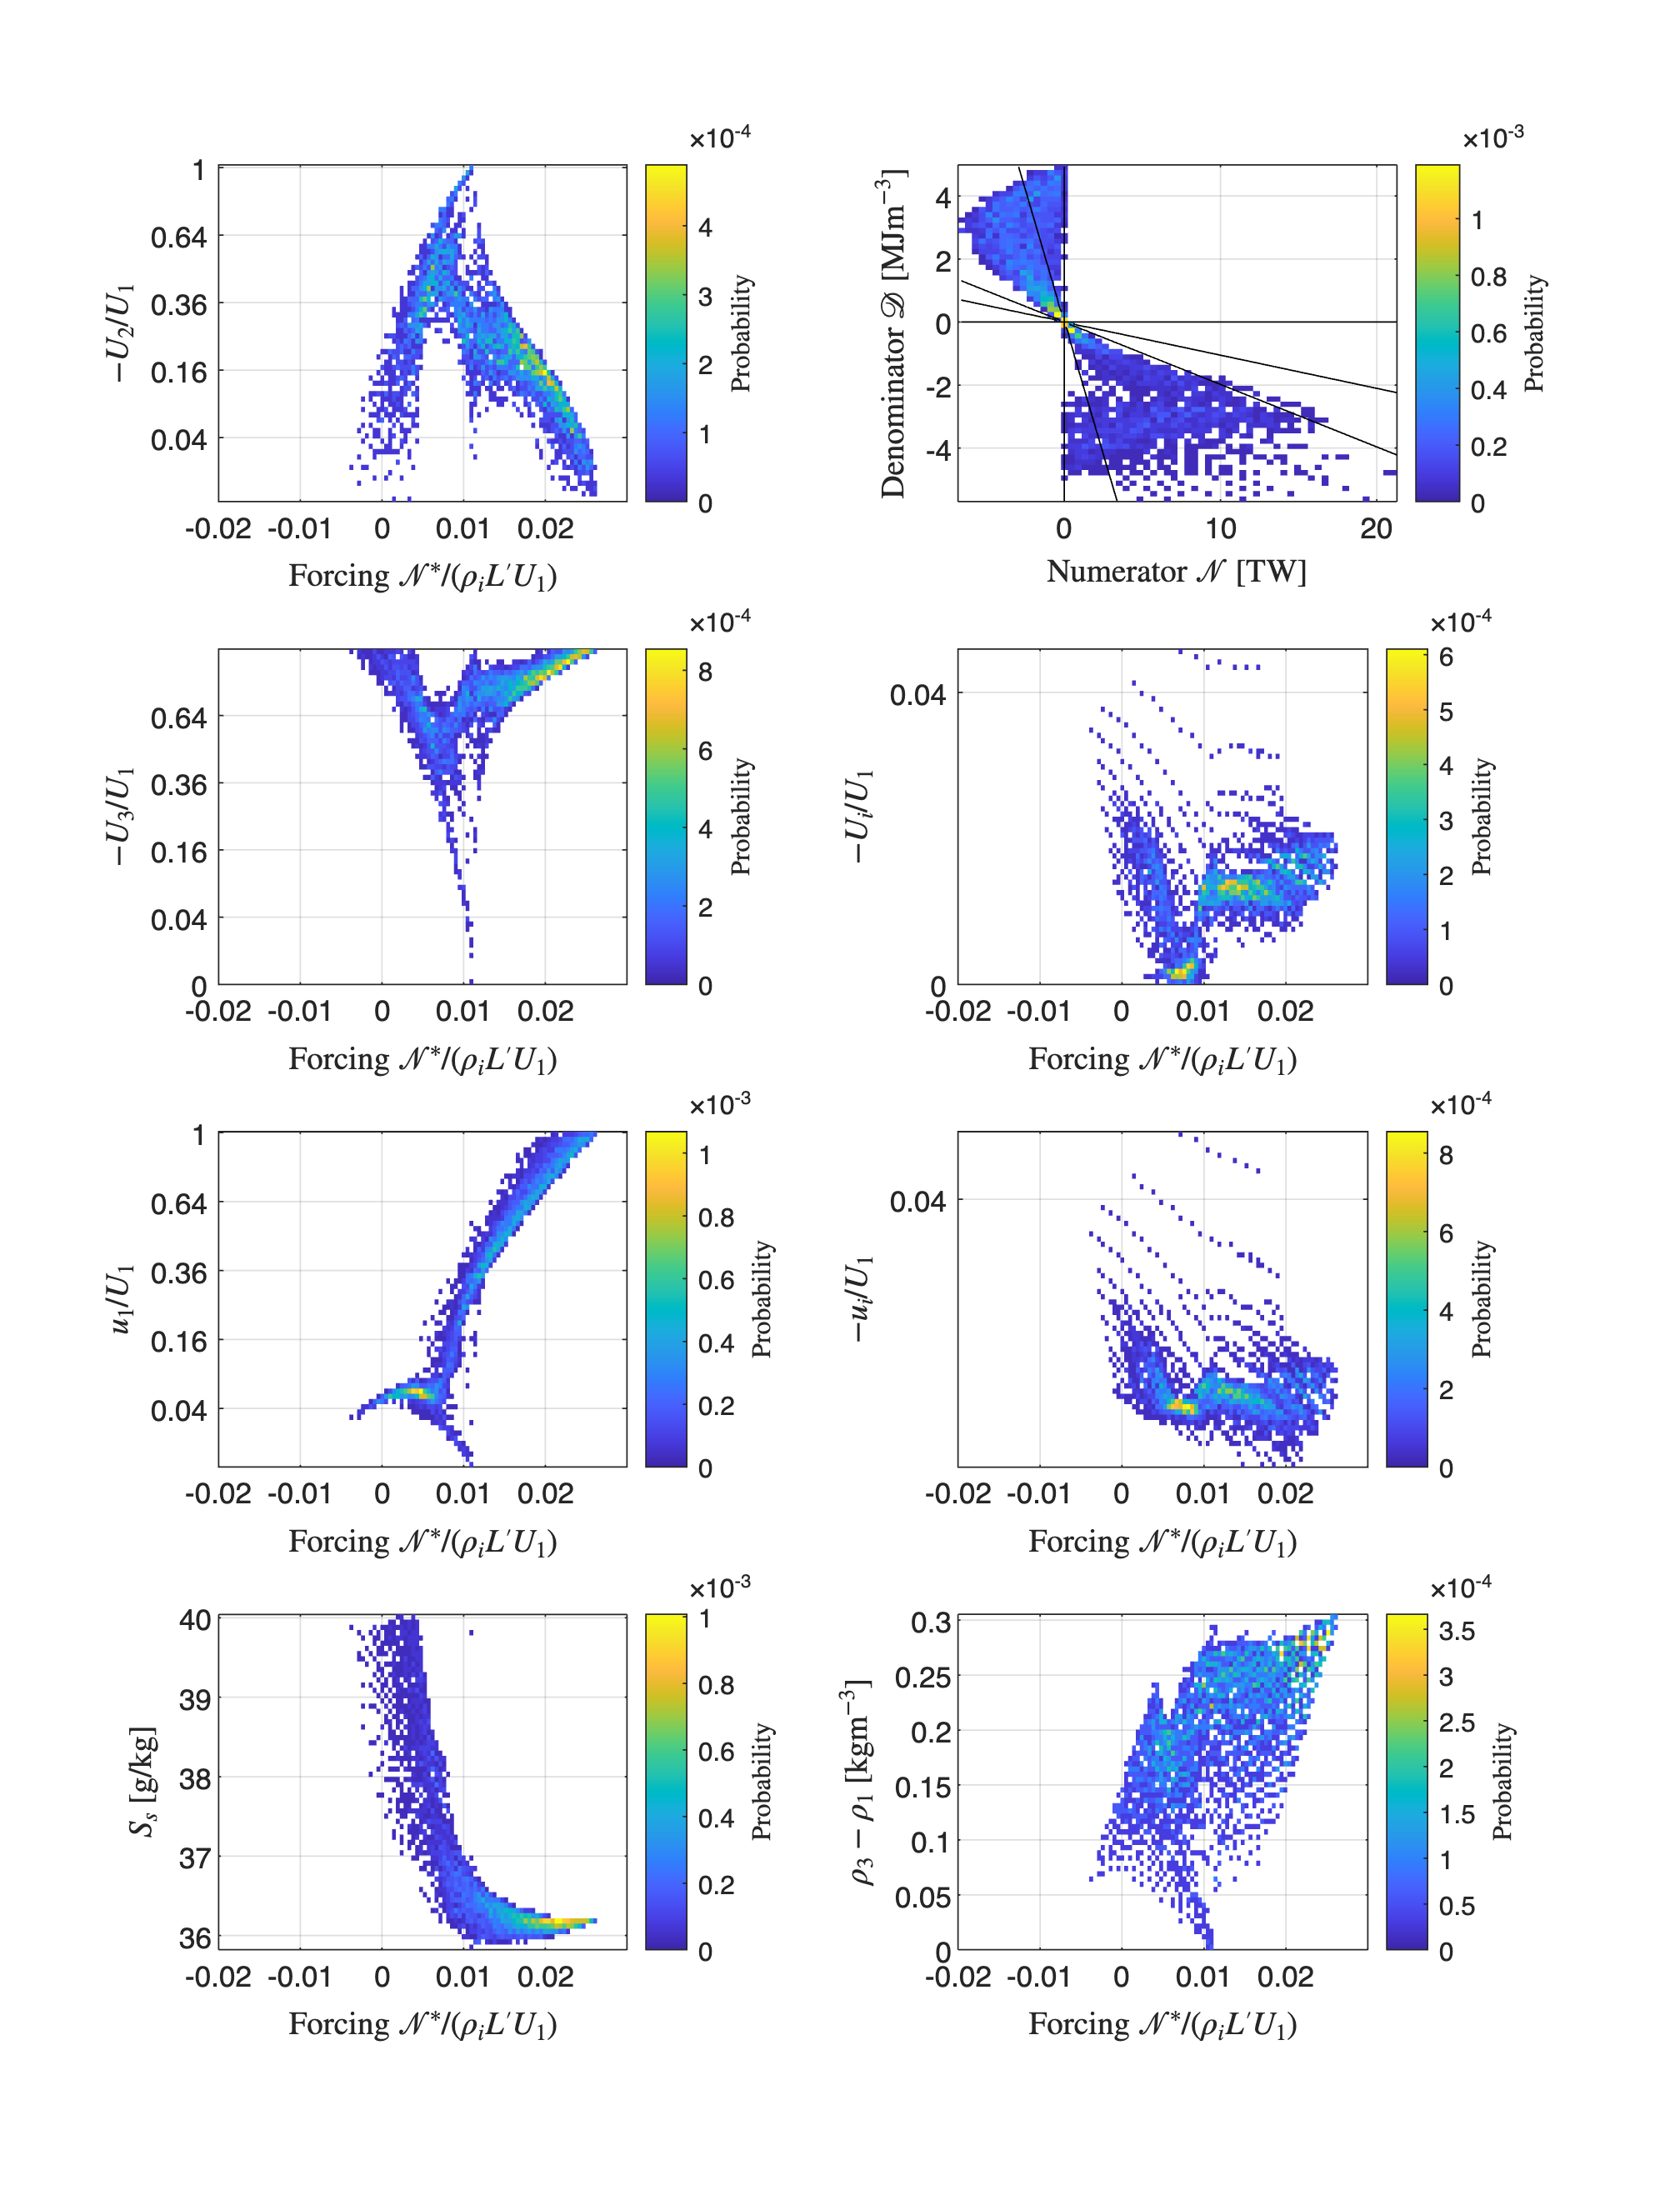

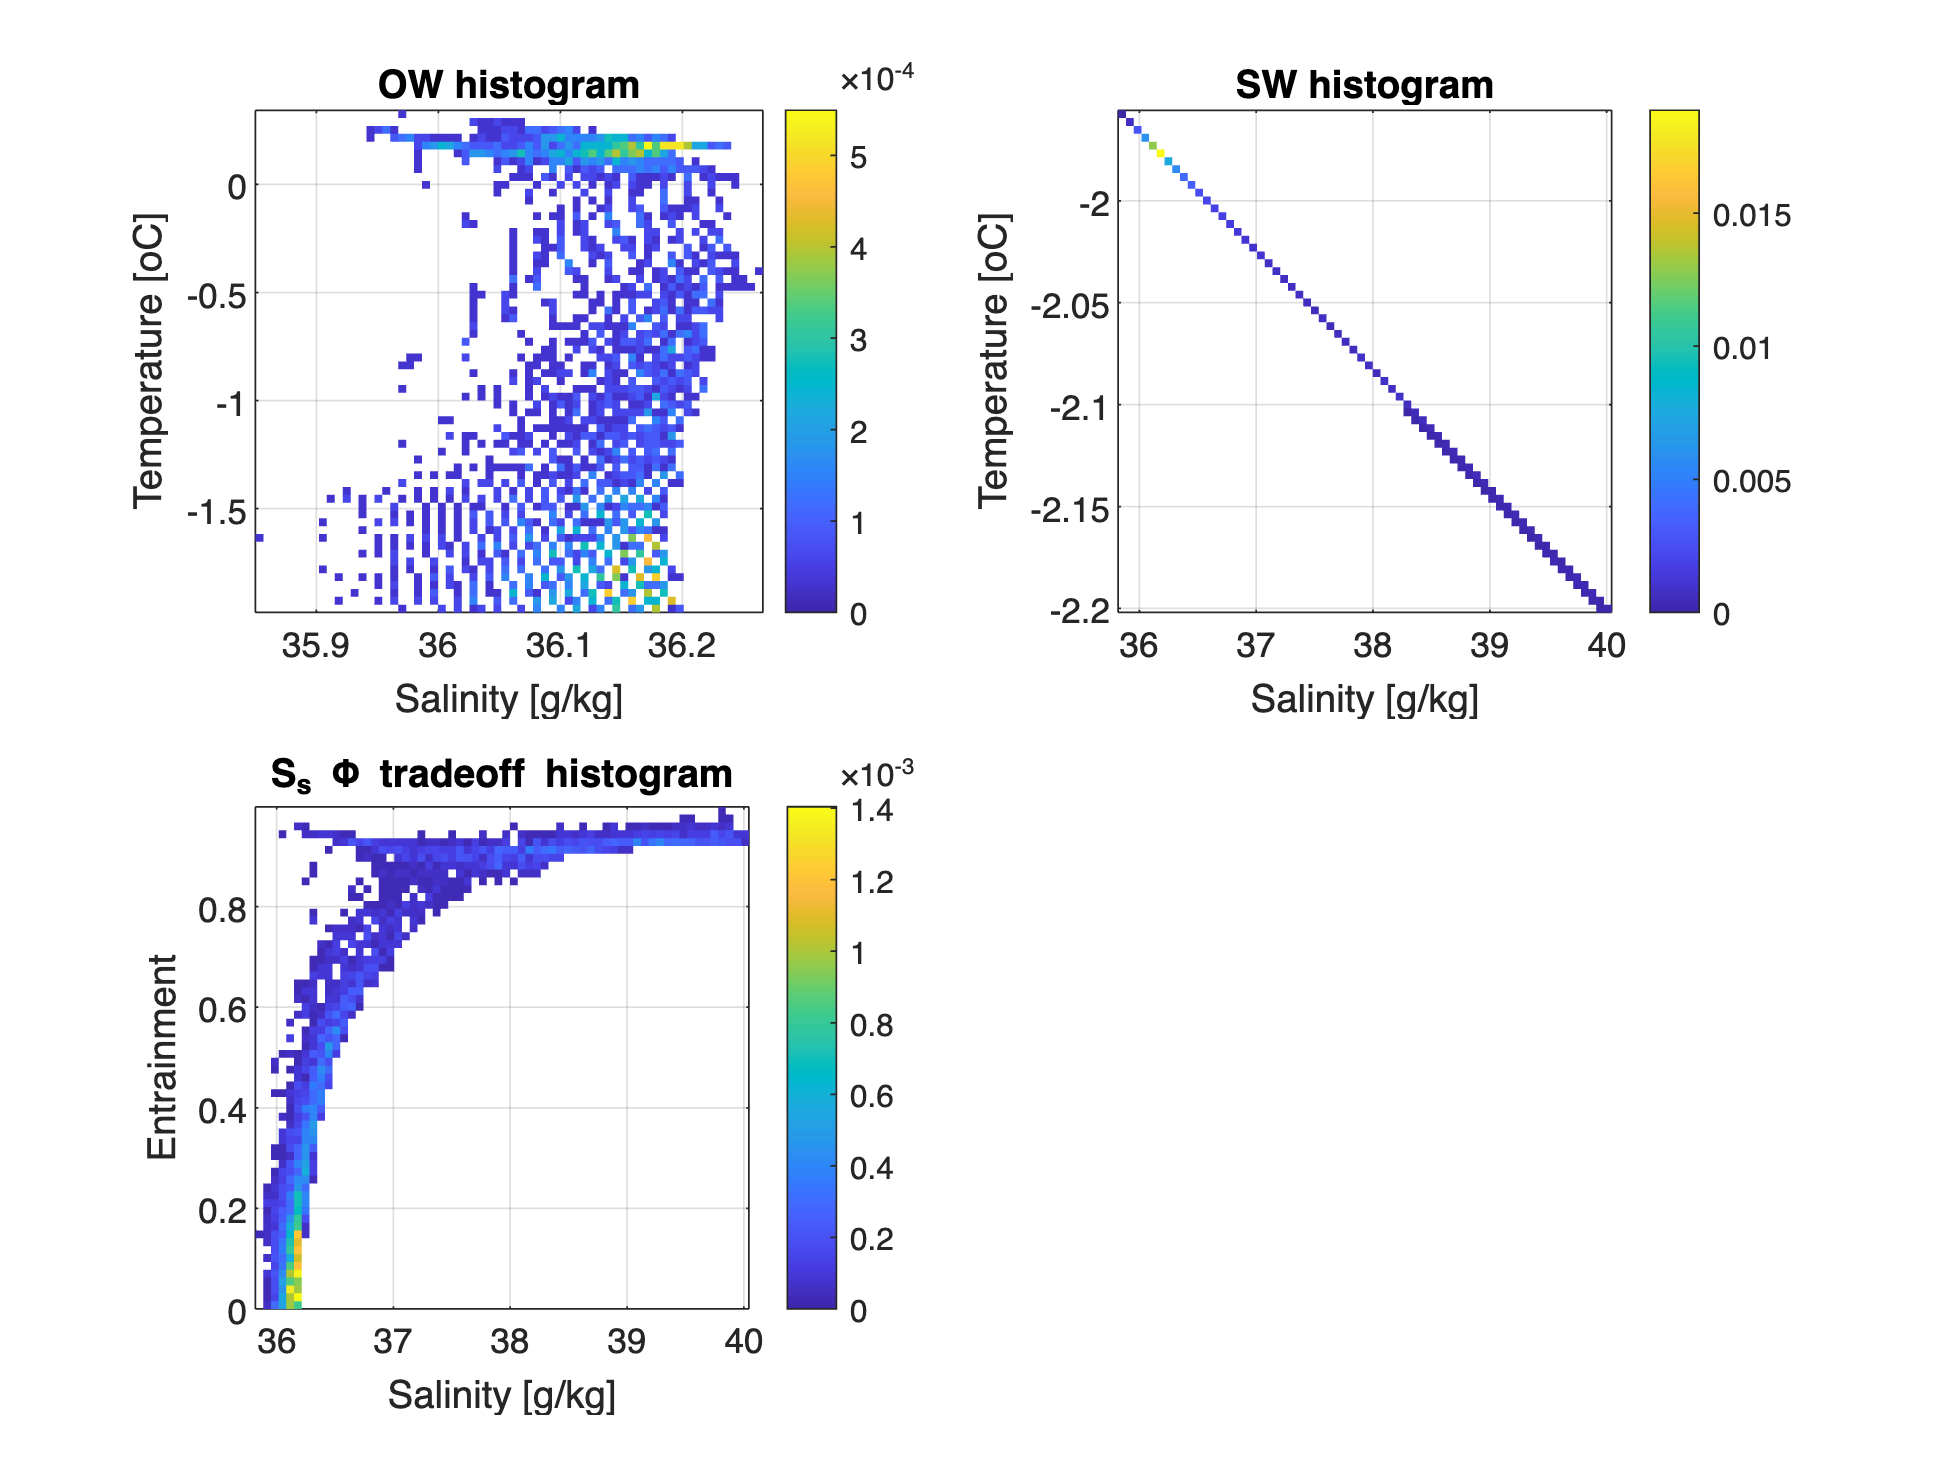

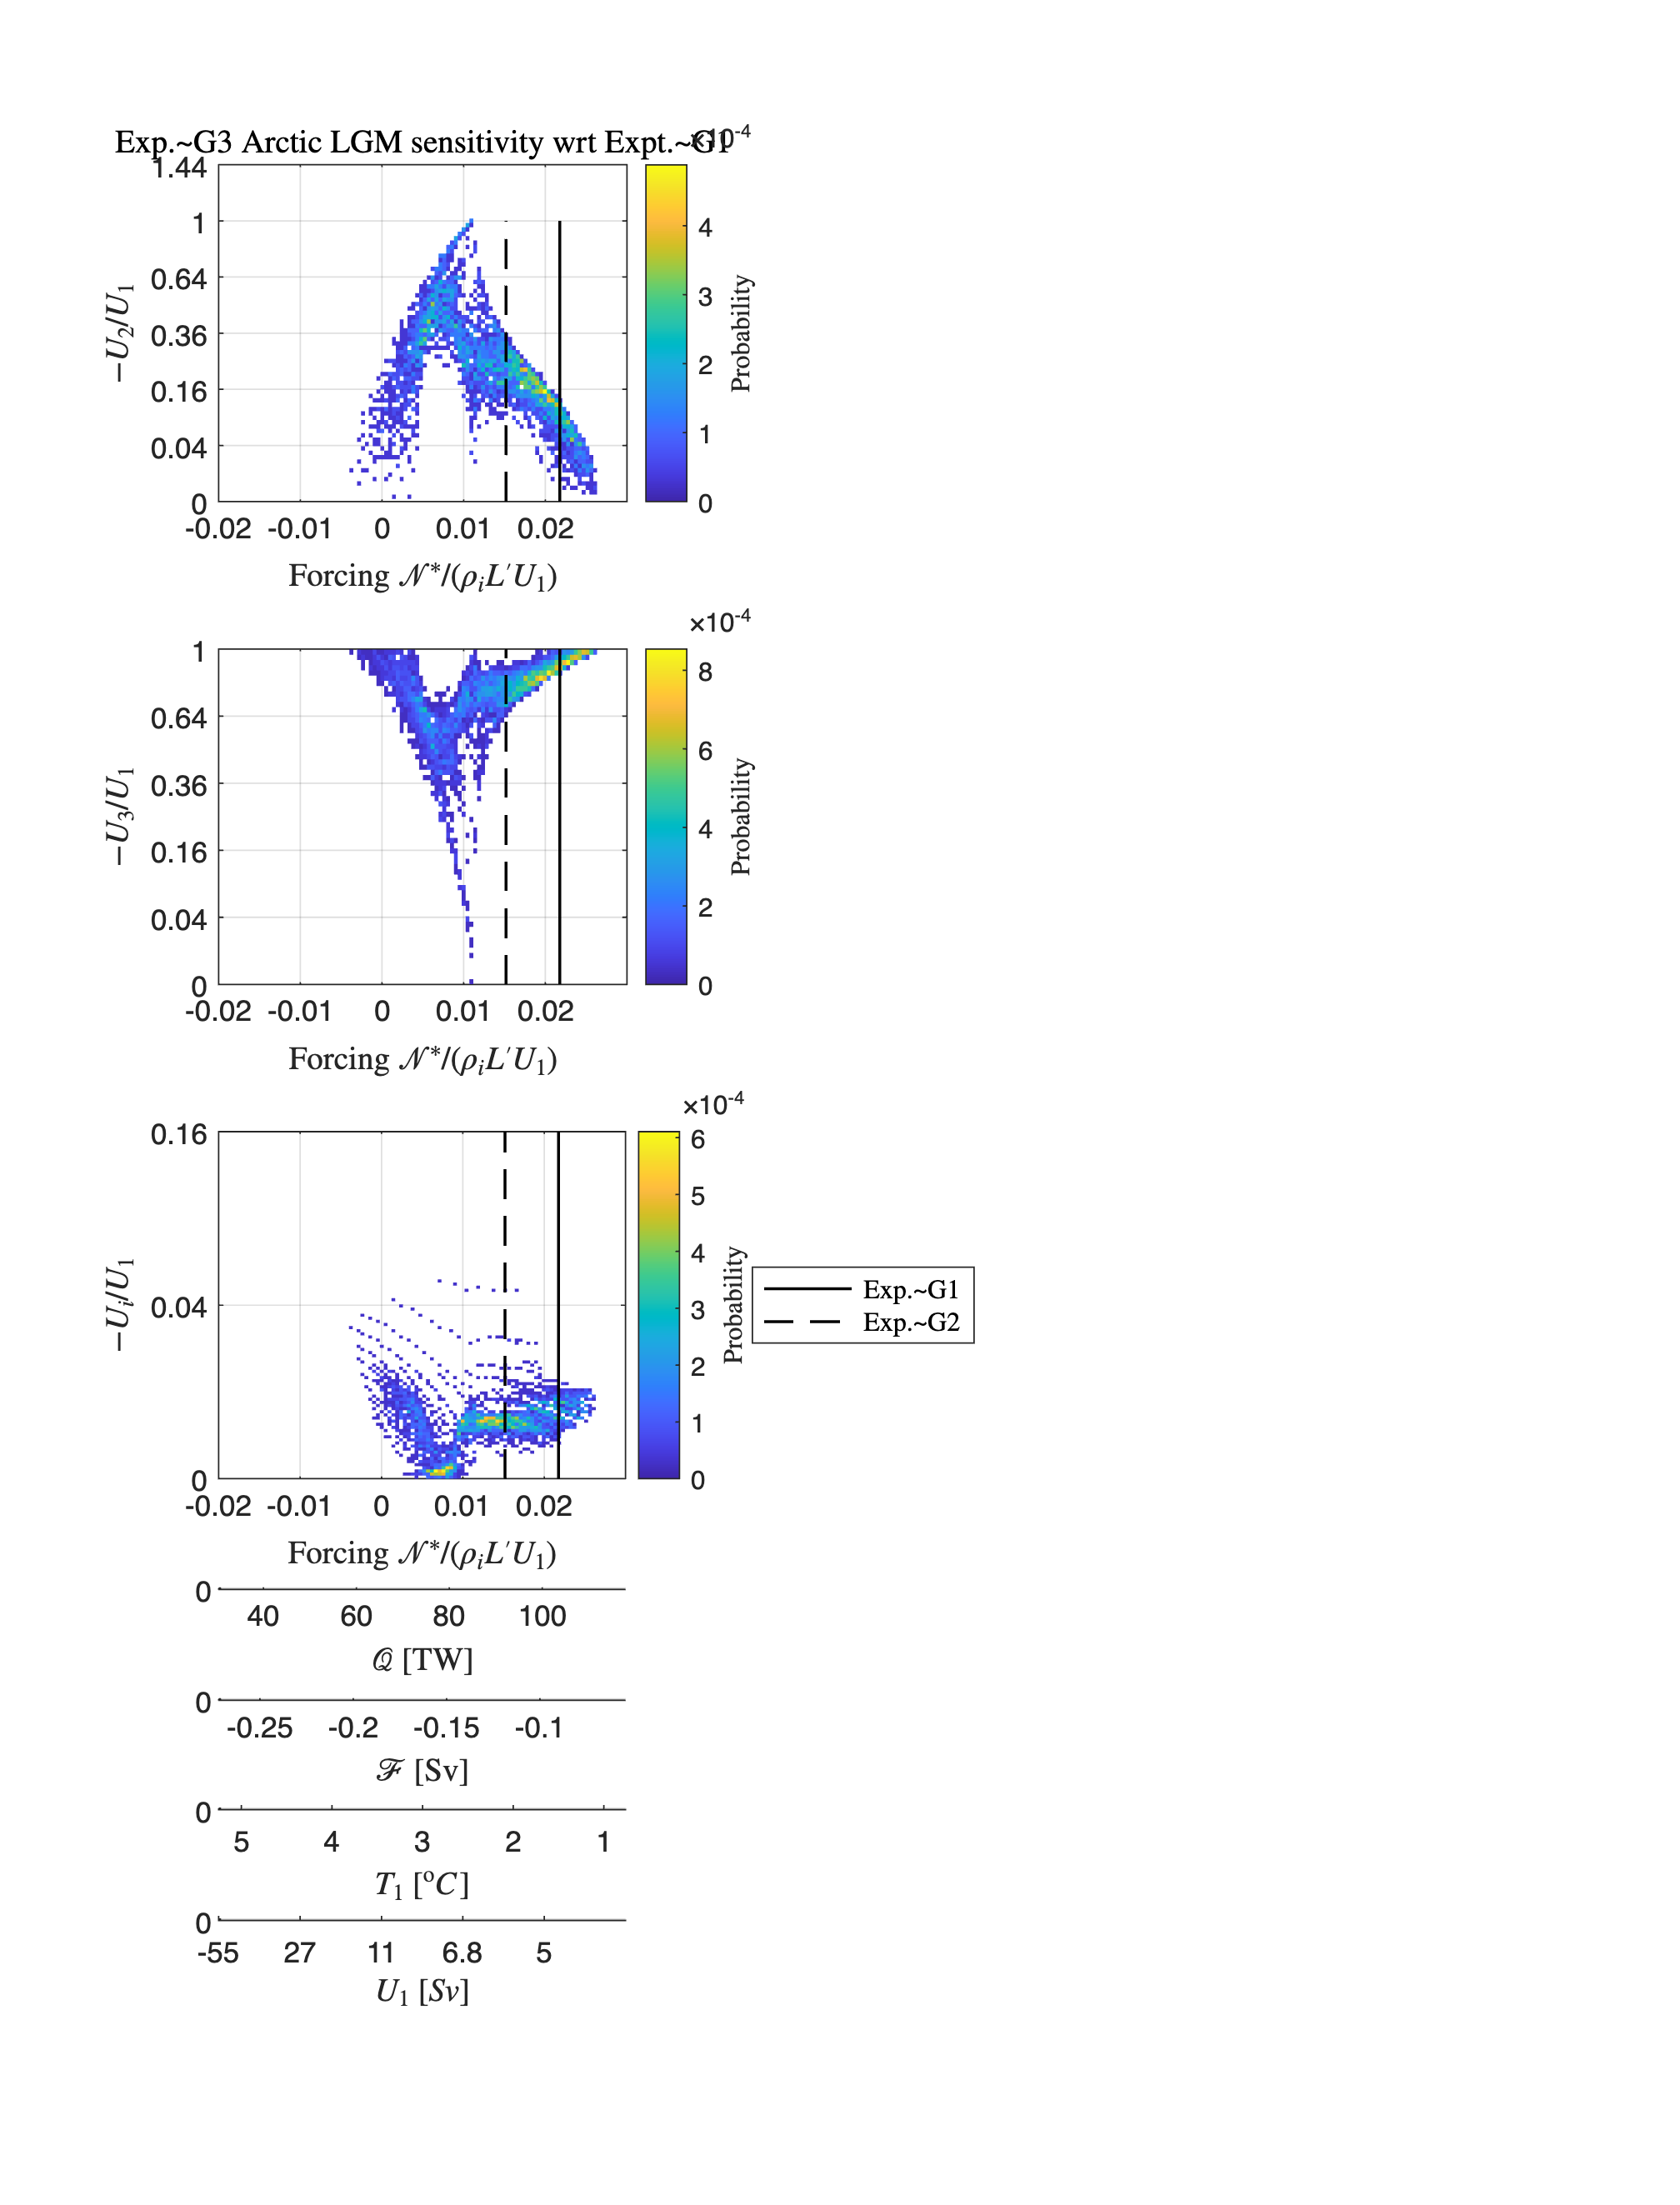

plot_POC_solutions2(modelG3,modelG1,modelG1,modelG2) ;

modelG3 = build_stable_isotope_model(modelG3) ;

 Stable isotope solutions for experiment: [Exp.~G3 Arctic LGM sensitivity wrt Expt.~G1] with file suffices: [NH_LGM_range_small]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           1999.87 to  2000.41  |     -0.29 to    -0.02          
 Overflow Water:           1983.58 to  2000.42  |     -8.45 to    -0.01          
 Sea ice:                  1947.19 to  2000.42  |    -26.67 to    -0.01           
 Shelf    Water:           1947.19 to  2000.42  |    -26.67 to    -0.01           



save('modelG3_with18O.mat','modelG3')

Exp G3b: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values including varying T_1.

modelG3b = build_POC_model('NH_LGM_range_small_incl_T1') ;

------------------------------------------------------------------------------------------------------------------------
------------------------------------------------------------------------------------------------------------------------
 Solutions for experiment: [Exp.~G3b Arctic LGM sensitivity wrt Expt.~G1 including T1] with file suffices: [NH_LGM_range_small_incl_T1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             1.1250   4.5625   8.0000 |  36.0500  36.0500  36.0500 |   0.5938   5.0469   9.5000
 Atlantic Water to shelf:    1.1250   4.5625   8.0000 |  36.0500  36.0500  36.0500 |   0.0003   2.4246   9.4949
 Polar    Water:            -1.9515  -1.9068

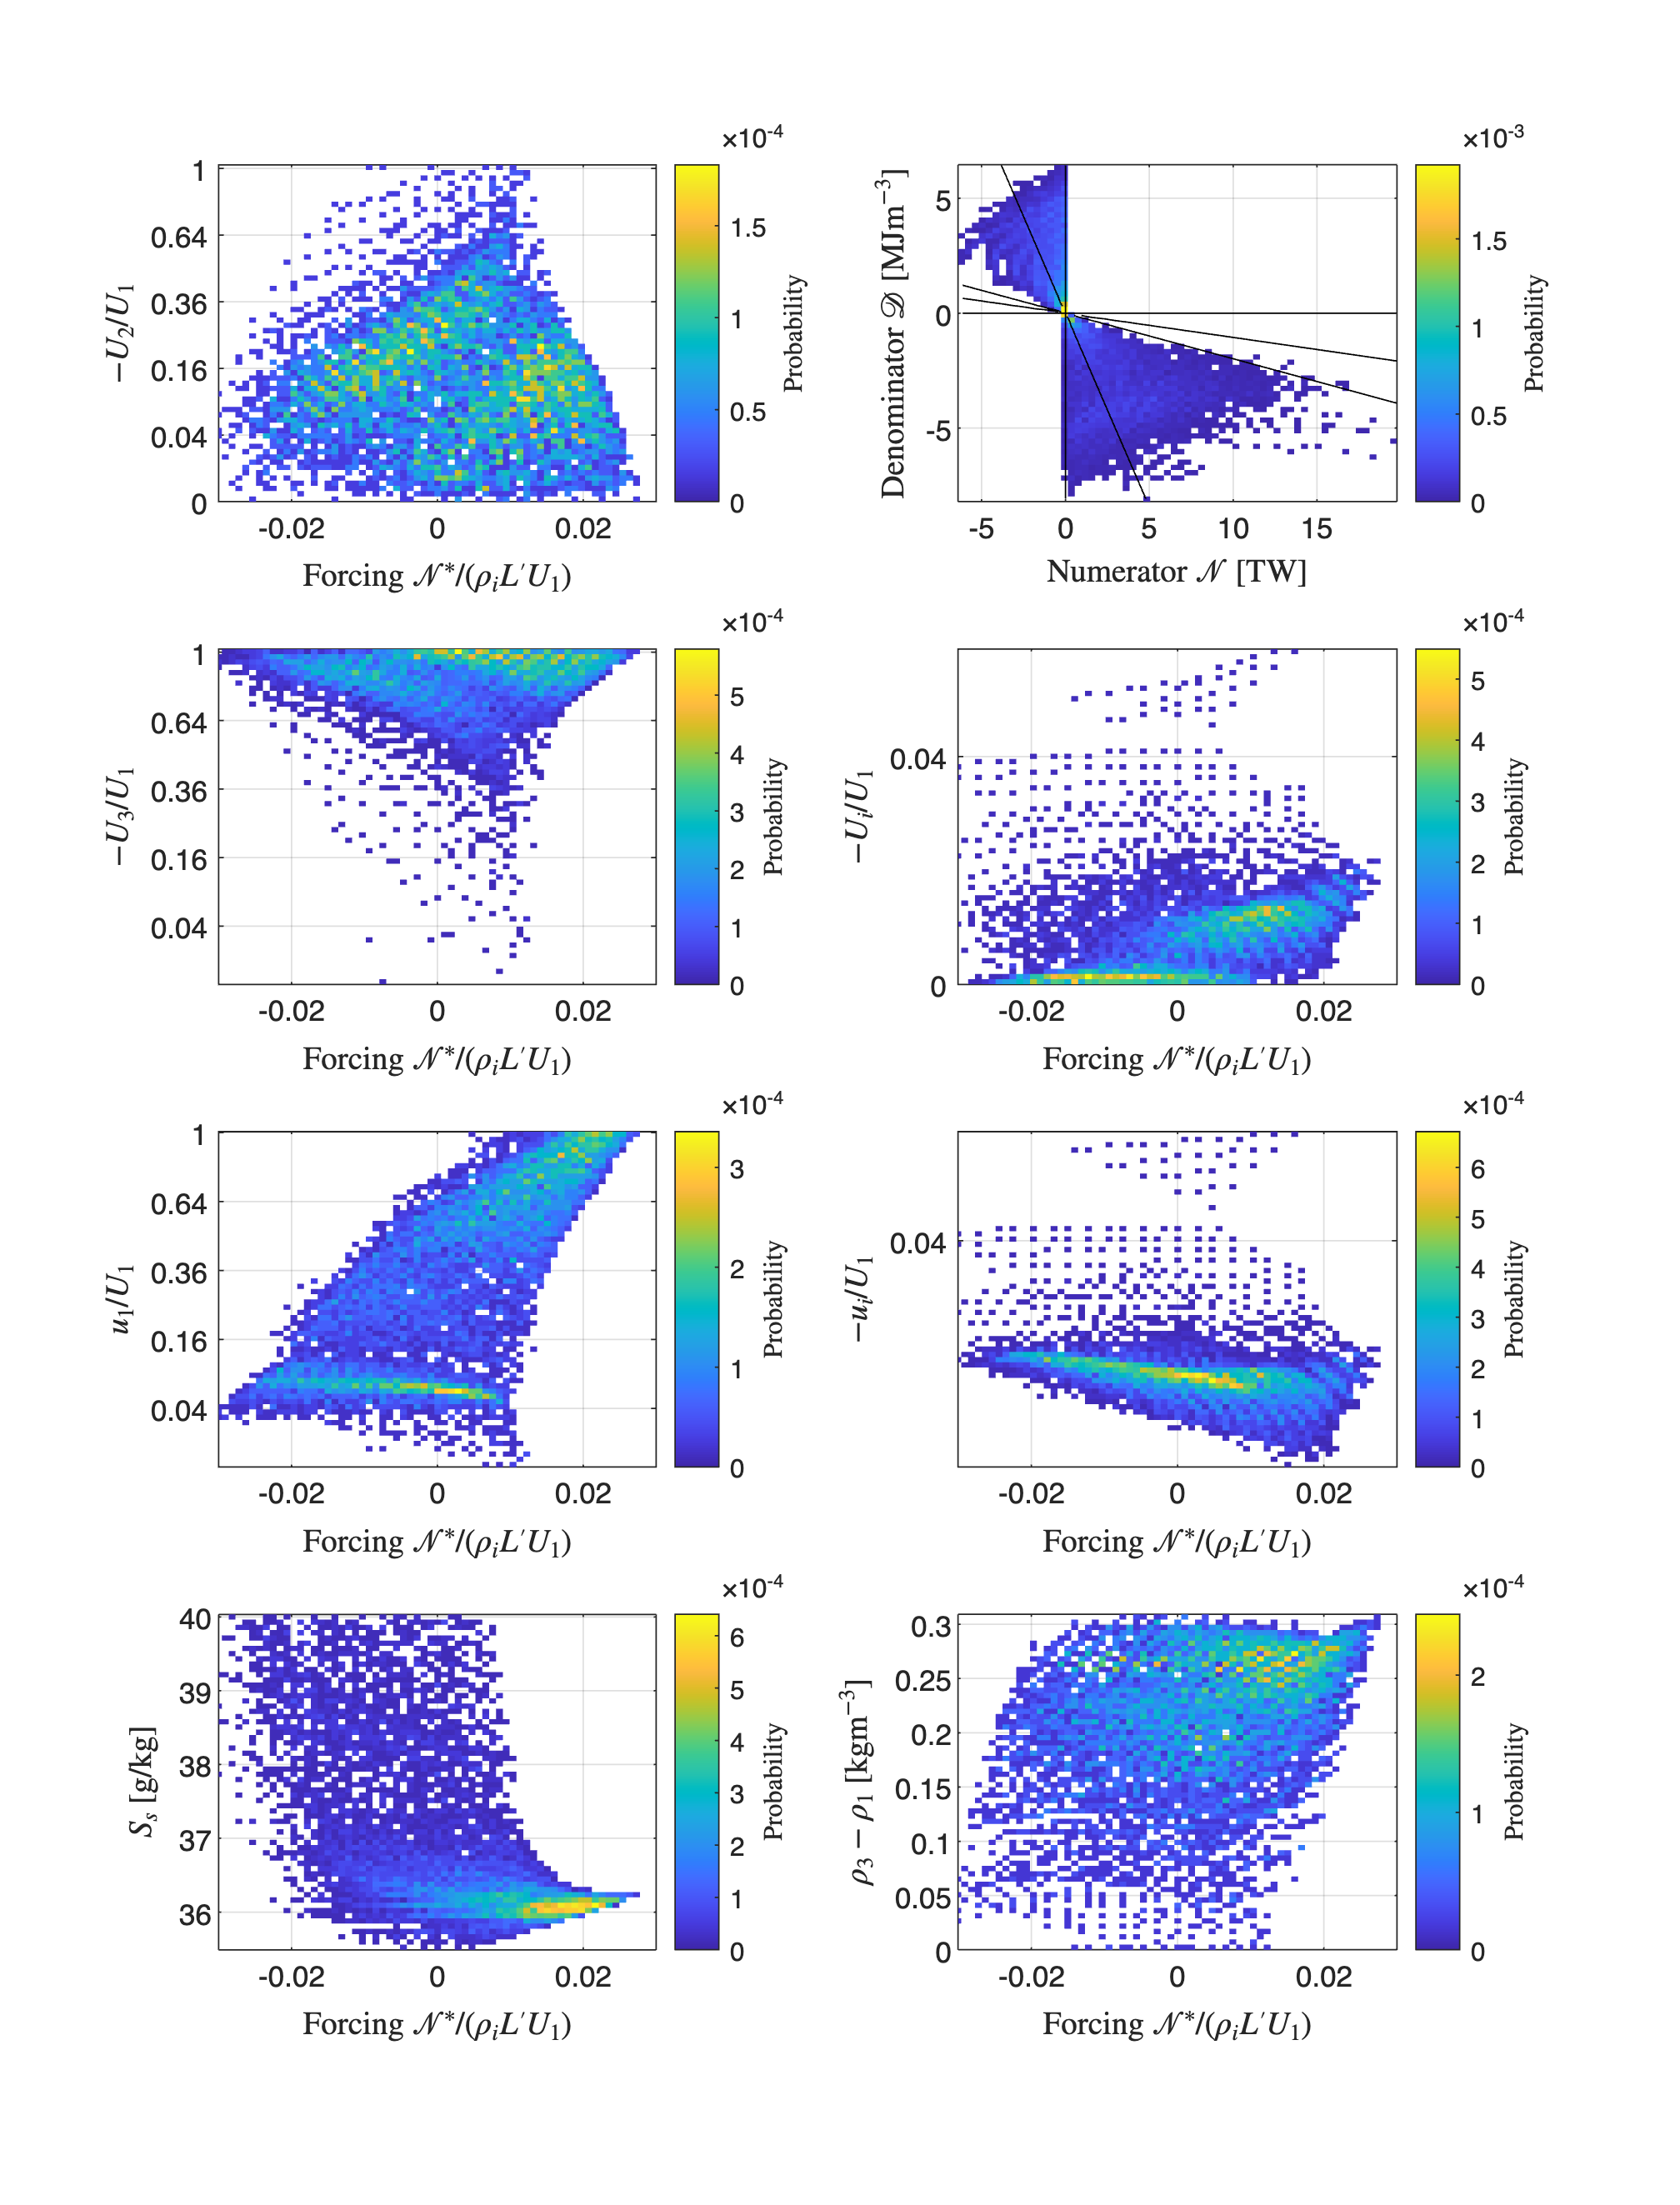

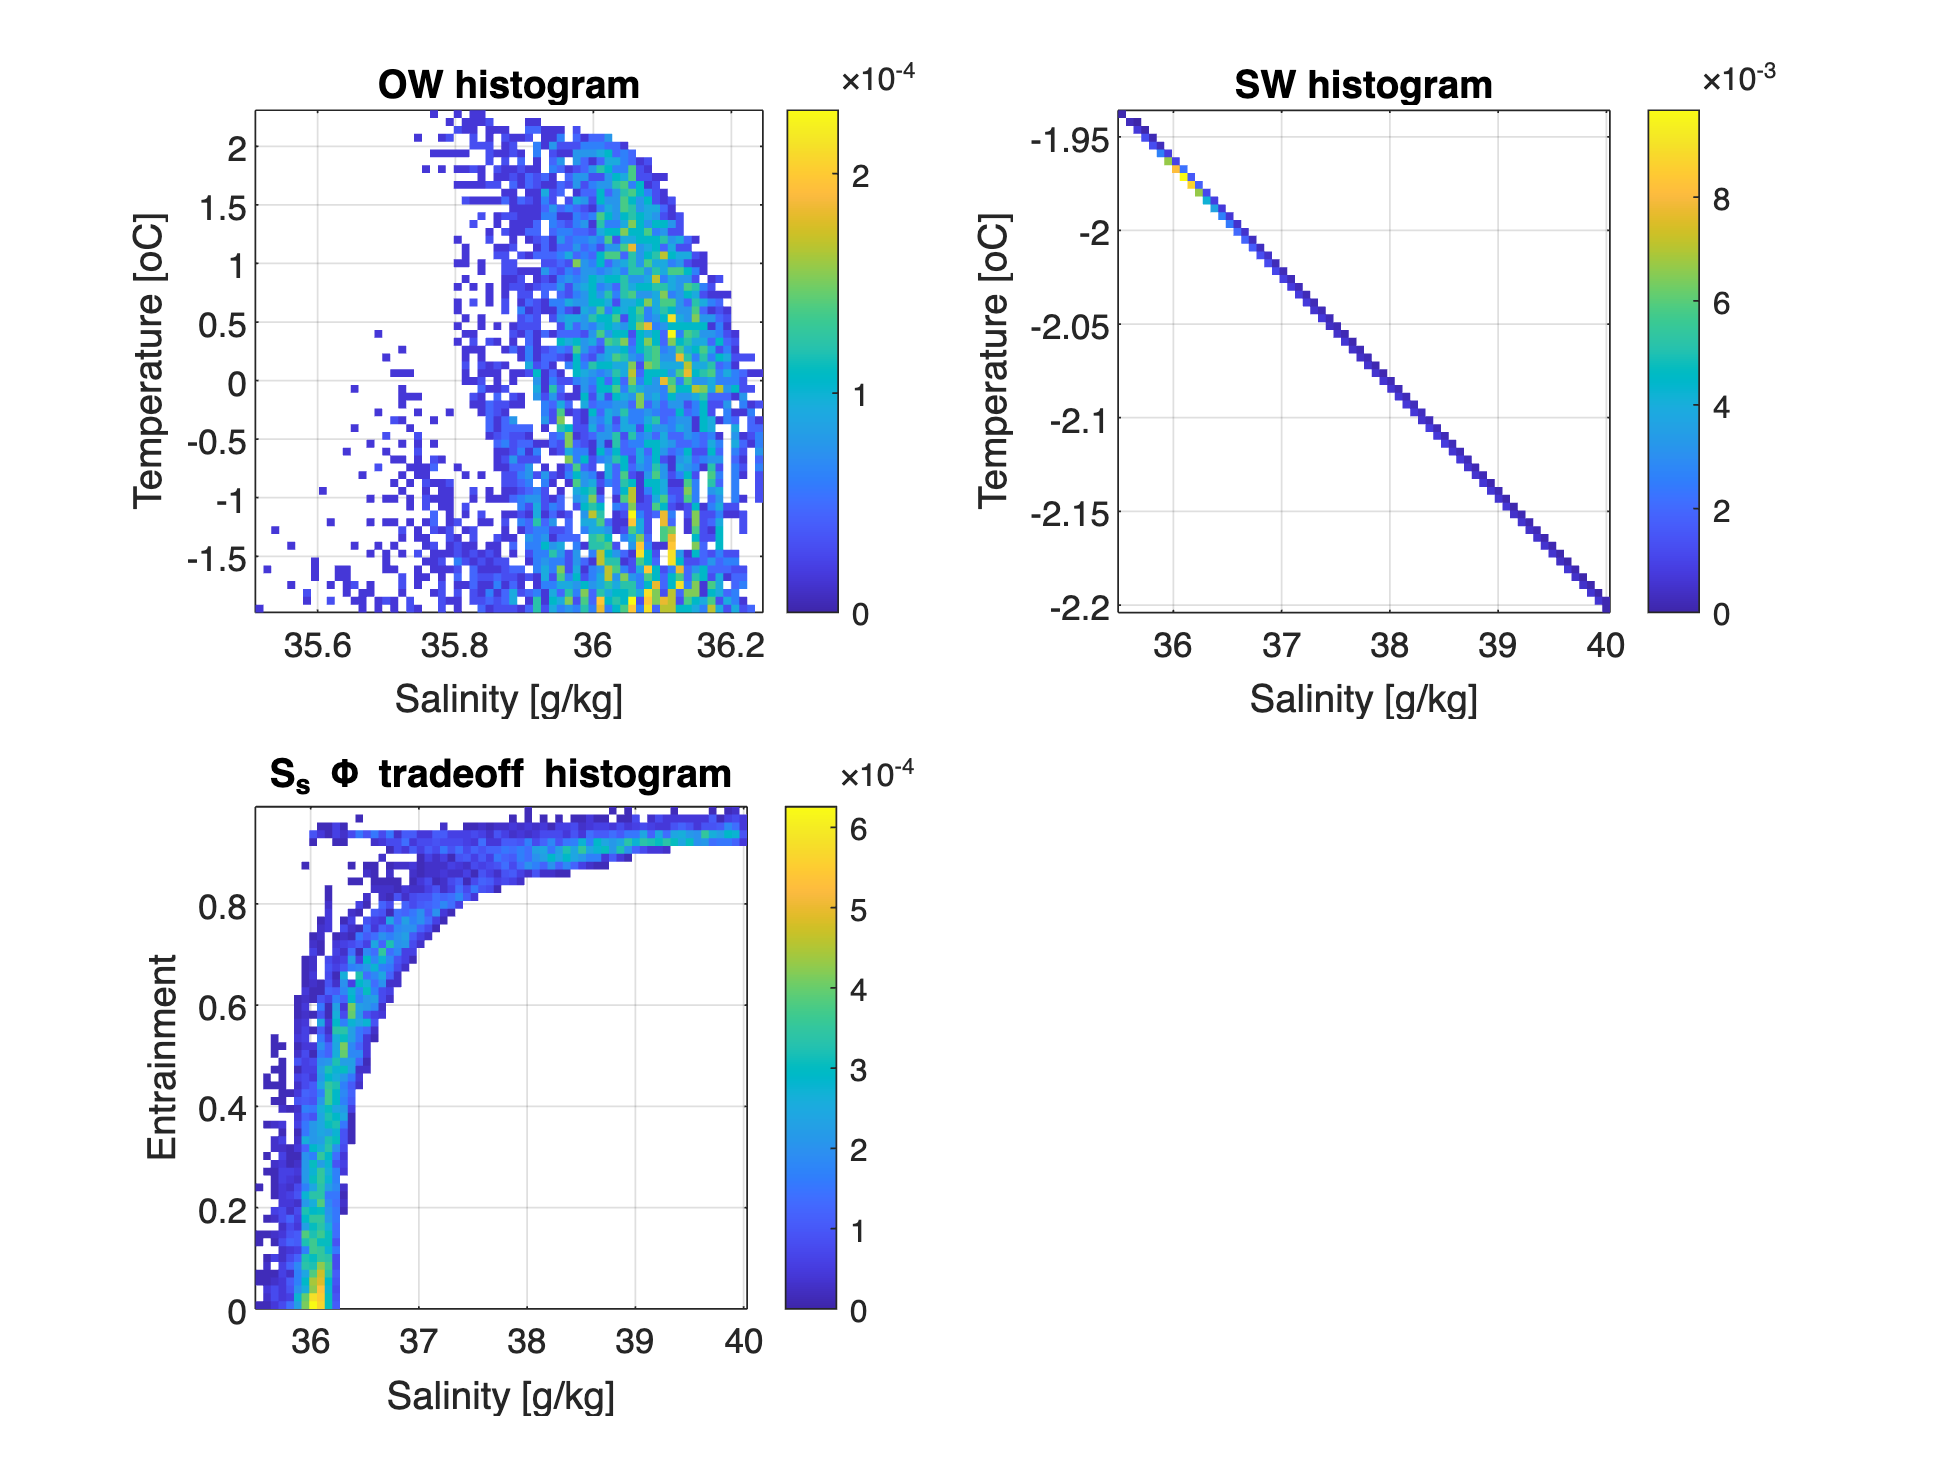

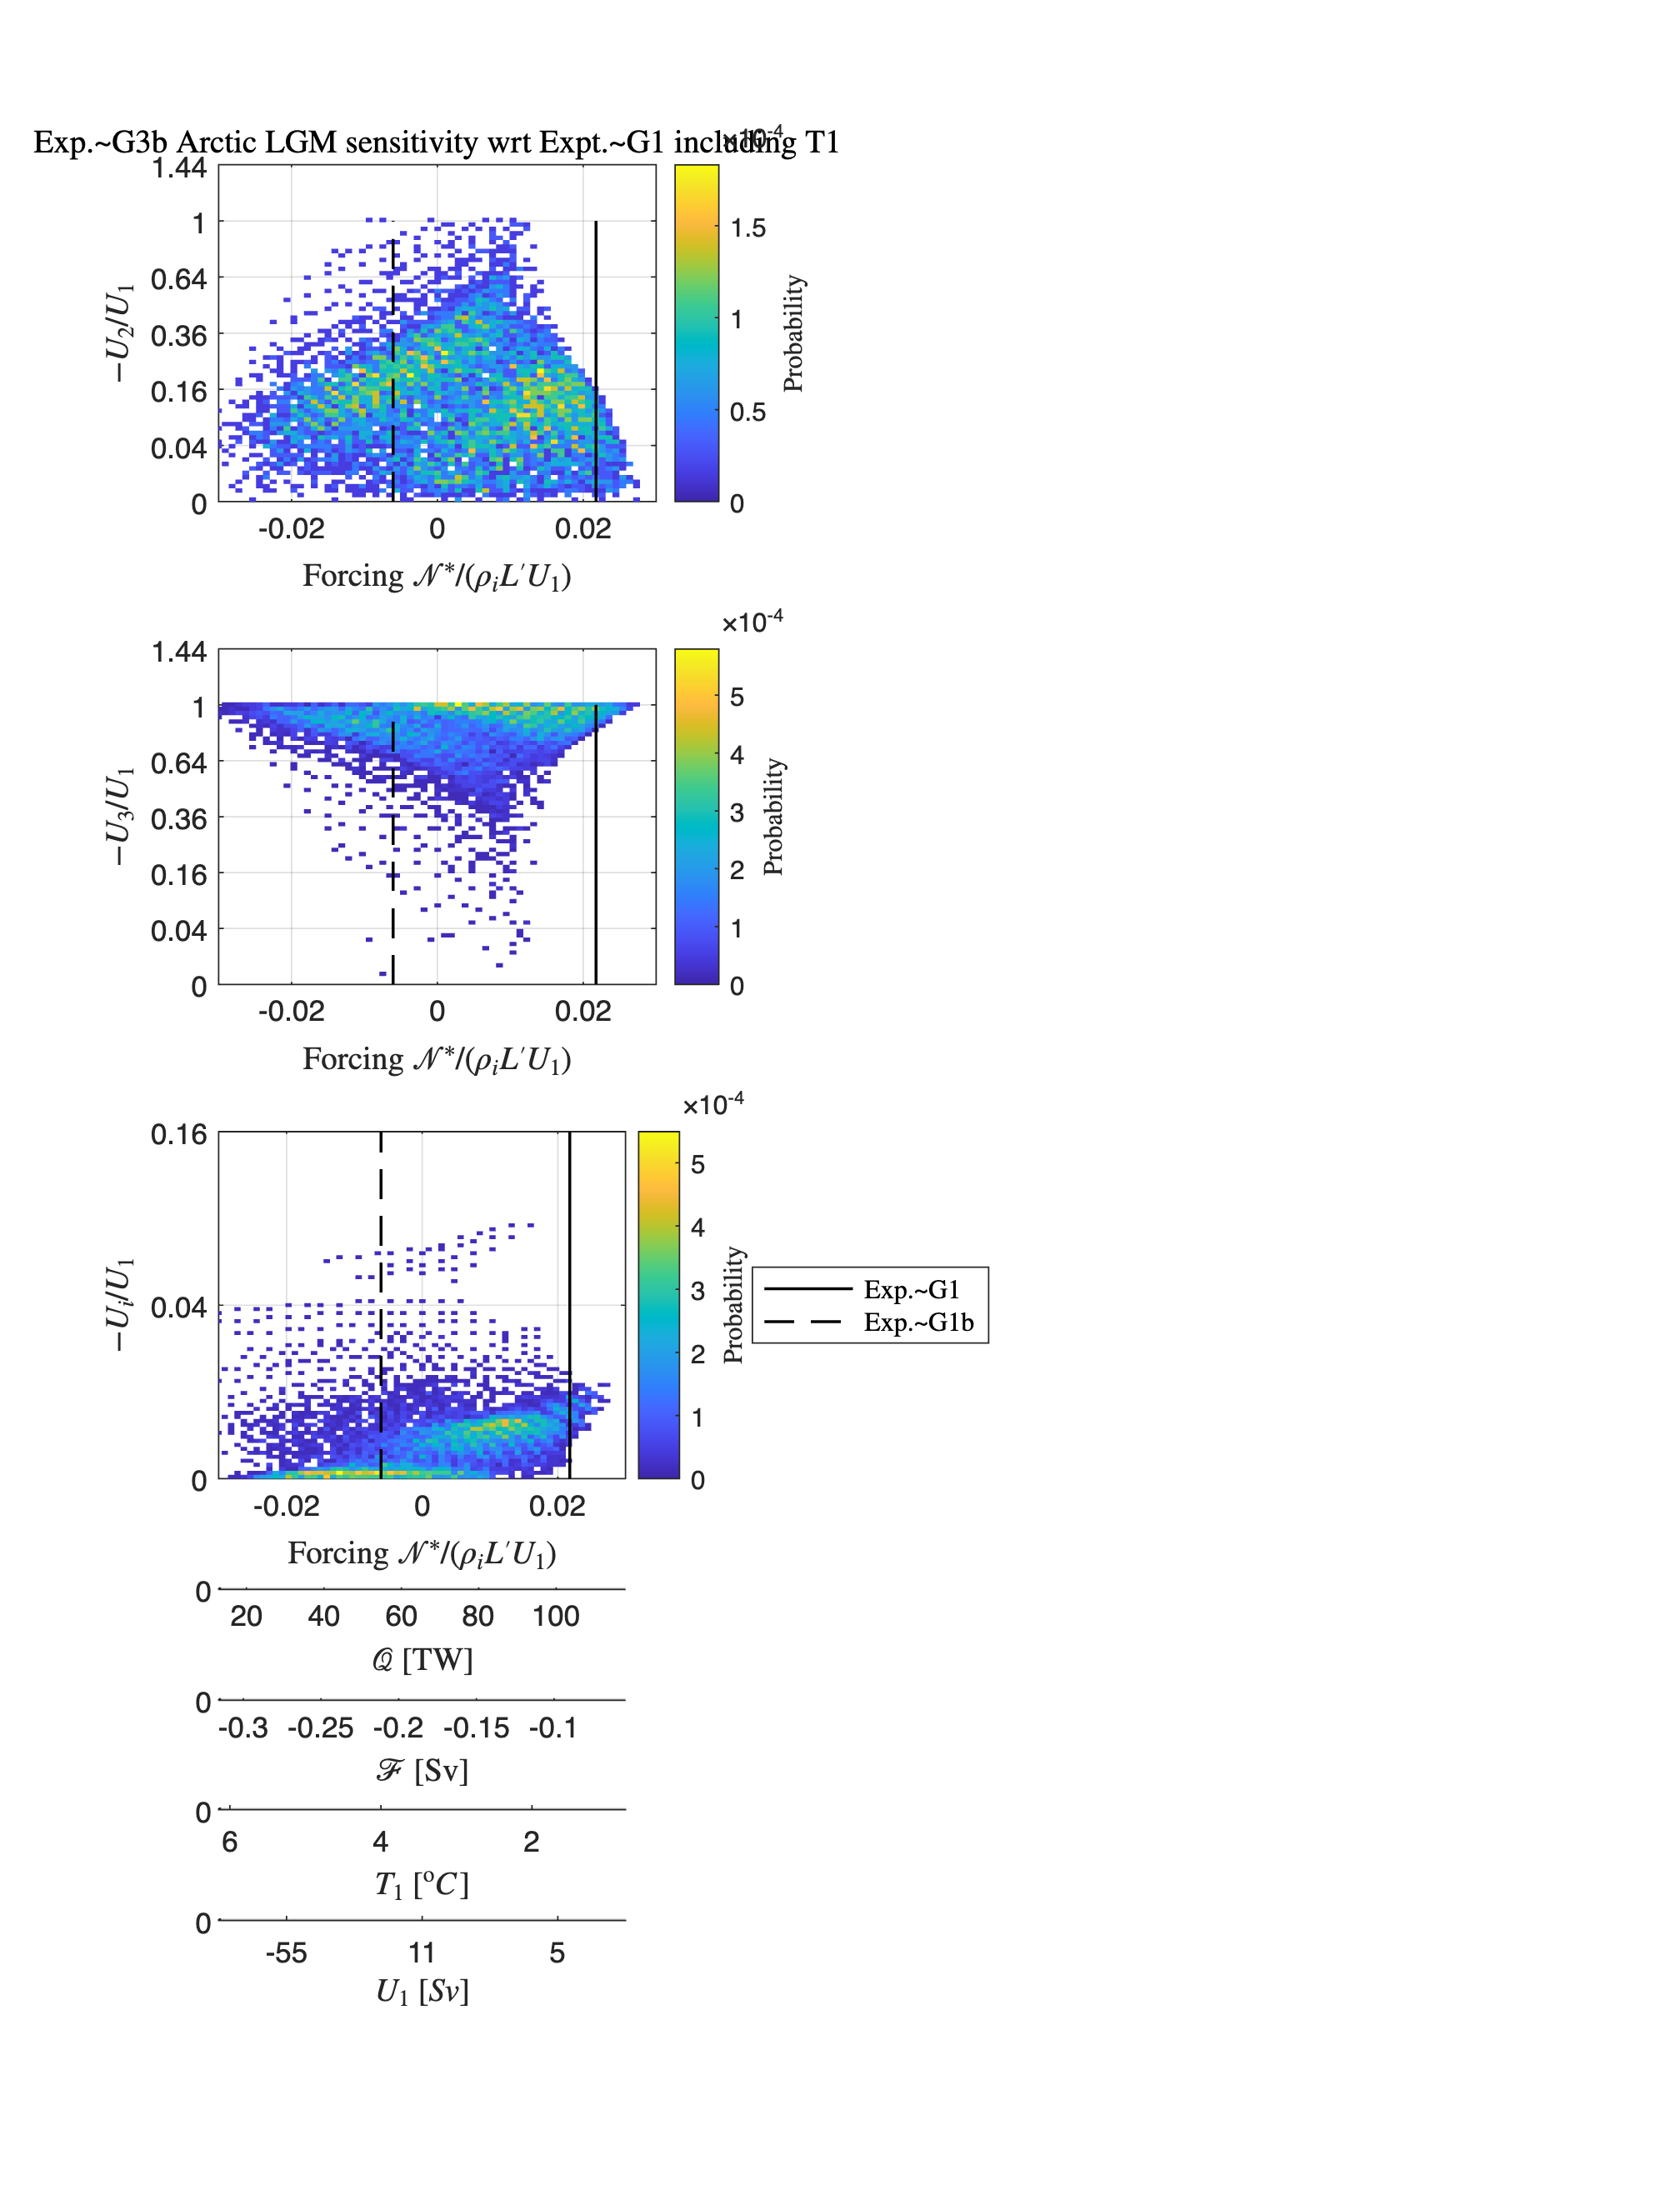

plot_POC_solutions2(modelG3b,modelG1,modelG1,modelG1b) ;

modelG3b = build_stable_isotope_model(modelG3b) ;

 Stable isotope solutions for experiment: [Exp.~G3b Arctic LGM sensitivity wrt Expt.~G1 including T1] with file suffices: [NH_LGM_range_small_incl_T1]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           1997.97 to  2000.41  |     -1.24 to    -0.02          
 Overflow Water:           1985.68 to  2000.42  |     -7.40 to    -0.01          
 Sea ice:                  1947.29 to  2000.42  |    -26.62 to    -0.01           
 Shelf    Water:           1947.29 to  2000.42  |    -26.62 to    -0.01           


Exp G3c: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values and high T_1 (warm AW).

return
modelG3c = build_POC_model('NH_LGM_range_small_hiT1') ;
plot_POC_solutions2(modelG3c,modelG1,modelG1,modelG1b) ;
modelG3c = build_stable_isotope_model(modelG3c) ;
save('modelG3c_with18O.mat','modelG3c')

Exp G4: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

modelG4 = build_POC_model('NH_LGM_range_big') ;
plot_POC_solutions2(modelG4,modelG1,modelG1,modelG1b) ;
modelG4 = build_stable_isotope_model(modelG4) ;

Exp G4b: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values and high T_1 (warm AW).

modelG4b = build_POC_model('NH_LGM_range_big_hiT1') ;
plot_POC_solutions2(modelG4b,modelG1,modelG1,modelG1b) ;
modelG4b = build_stable_isotope_model(modelG4b) ;

% Patrick type plot from 7Nov22:
scatter(modelG4b.dynamic_parameters.Q./1e12,-modelG4b.sens.U_3can.*(modelG4b.sens.T_3can - modelG4b.sens.Tfs)./1e6,[],modelG4b.dynamic_parameters.U_1./1e6,'filled')
xlabel('Q [TW]')
ylabel('-U3 \DeltaT3 [Sv K]')
cb = colorbar ;
cb.Label.String = 'U1 [Sv]' ;
grid on